# Data to use for aggregation, WSN Mini-project

close all, clear, clc;
%source1_data = randi([15,30],100,1)';
%source2_data = randi([18,25],100,1)';
%source3_data = randi([12,21],100,1)';
%source4_data = randi([8,16],100,1)';
load('test.mat')

time = 1:1:length(source1_data(1:50));
%time = 1:1:length(source1_data);


save('test.mat', "source1_data", "source2_data", "source3_data", "source4_data")

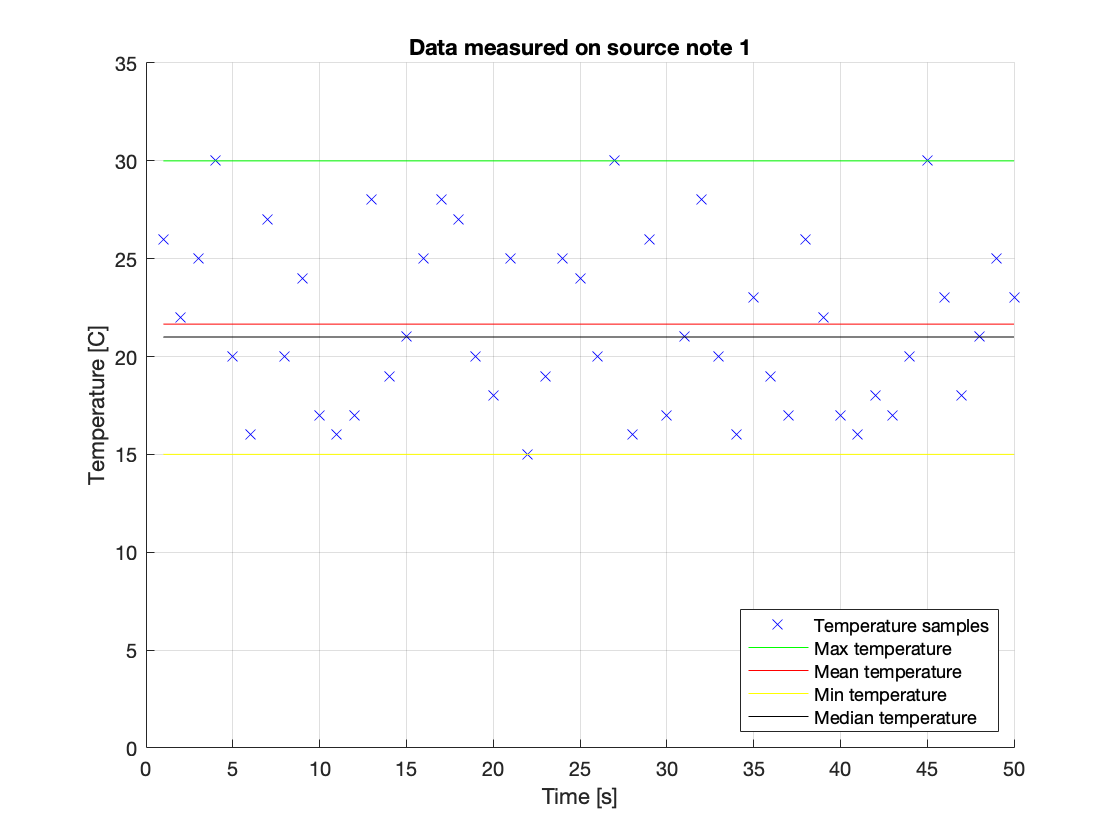

close all
s1_data = source1_data(1:50);
%s1_data = source1_data;
% Calculate mean, min, max and median of sensored data

source1_mean = mean(s1_data);
source1_min = min(s1_data);
source1_max = max(s1_data);
source1_median = median(s1_data);
source1_samples = length(s1_data);

% Plot the sampled and aggregated data
figure(1)
scatter(time, s1_data, 'x', 'b')
ylim([0;max(s1_data)+5]), grid
title('Data measured on source note 1')
xlabel('Time [s]'), ylabel('Temperature [C]')
hold on
plot(time, source1_max*ones(size(time)), 'g')
plot(time, source1_mean*ones(size(time)), 'r')
plot(time, source1_min*ones(size(time)),'y')
plot(time, source1_median*ones(size(time)),'k')
legend('Temperature samples', 'Max temperature', 'Mean temperature', 'Min temperature', 'Median temperature', location='southeast')

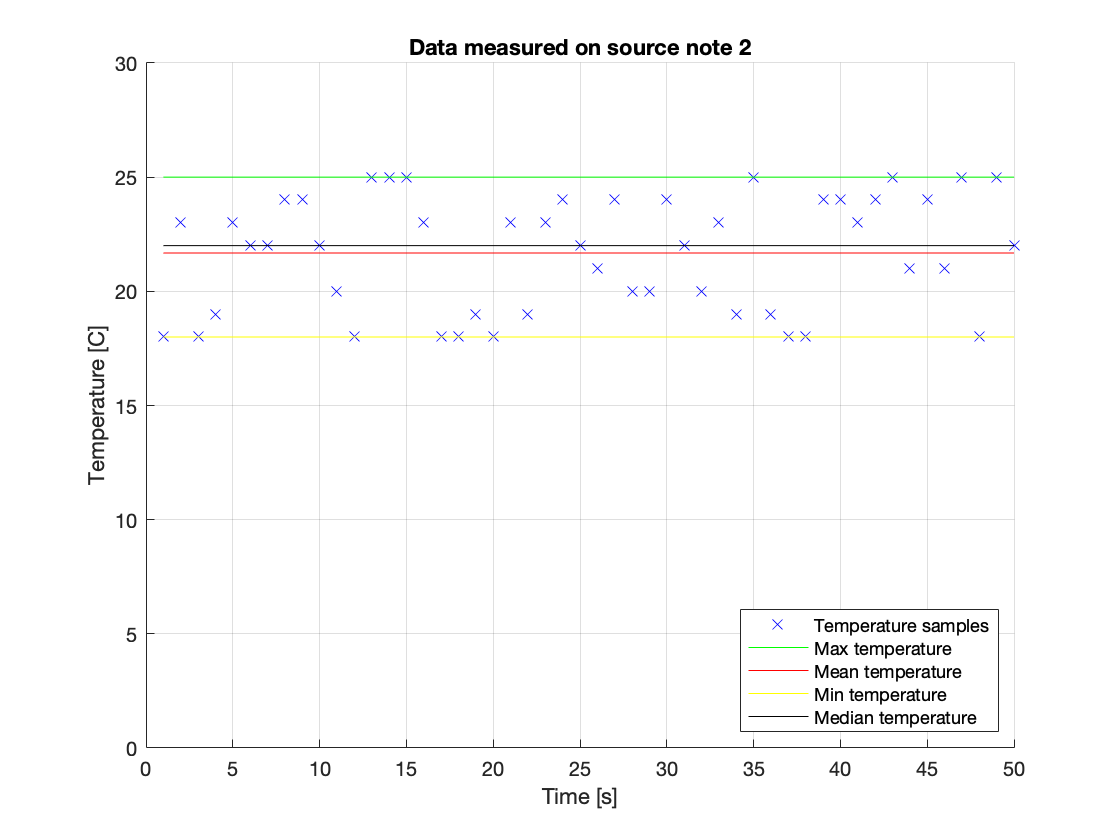

close all
s2_data = source2_data(1:50);
%s2_data = source2_data;
% Calculate mean, min, max and median of sensored data
source2_mean = mean(s2_data);
source2_min = min(s2_data);
source2_max = max(s2_data);
source2_median = median(s2_data);
source2_samples = length(s2_data);

% Plot the aggregated data
figure(2)
scatter(time, s2_data, 'x', 'b')
ylim([0;max(s2_data)+5]), grid
title('Data measured on source note 2')
xlabel('Time [s]'), ylabel('Temperature [C]')
hold on
plot(time, source2_max*ones(size(time)), 'g')
plot(time, source2_mean*ones(size(time)), 'r')
plot(time, source2_min*ones(size(time)),'y')
plot(time, source2_median*ones(size(time)),'k')
legend('Temperature samples', 'Max temperature', 'Mean temperature', 'Min temperature', 'Median temperature', location='southeast')

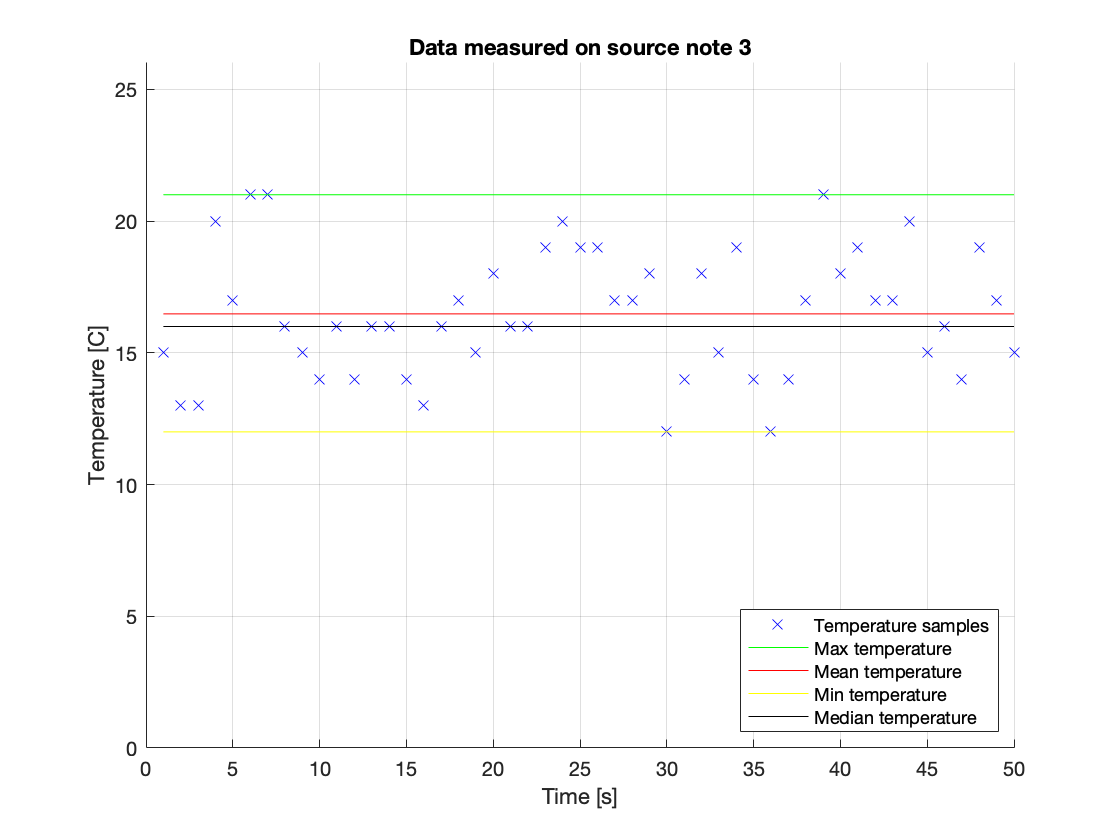

close all
s3_data = source3_data(1:50);
%s3_data = source3_data;
% Calculate mean, min, max and median of sensored data
source3_mean = mean(s3_data);
source3_min = min(s3_data);
source3_max = max(s3_data);
source3_median = median(s3_data);
source3_samples = length(s3_data);

% Plot the sampled and aggregated data
figure(3)
scatter(time, s3_data, 'x', 'b')
ylim([0;max(s3_data)+5]), grid
title('Data measured on source note 3')
xlabel('Time [s]'), ylabel('Temperature [C]')
hold on
plot(time, source3_max*ones(size(time)), 'g')
plot(time, source3_mean*ones(size(time)), 'r')
plot(time, source3_min*ones(size(time)),'y')
plot(time, source3_median*ones(size(time)),'k')
legend('Temperature samples', 'Max temperature', 'Mean temperature', 'Min temperature', 'Median temperature', location='southeast')

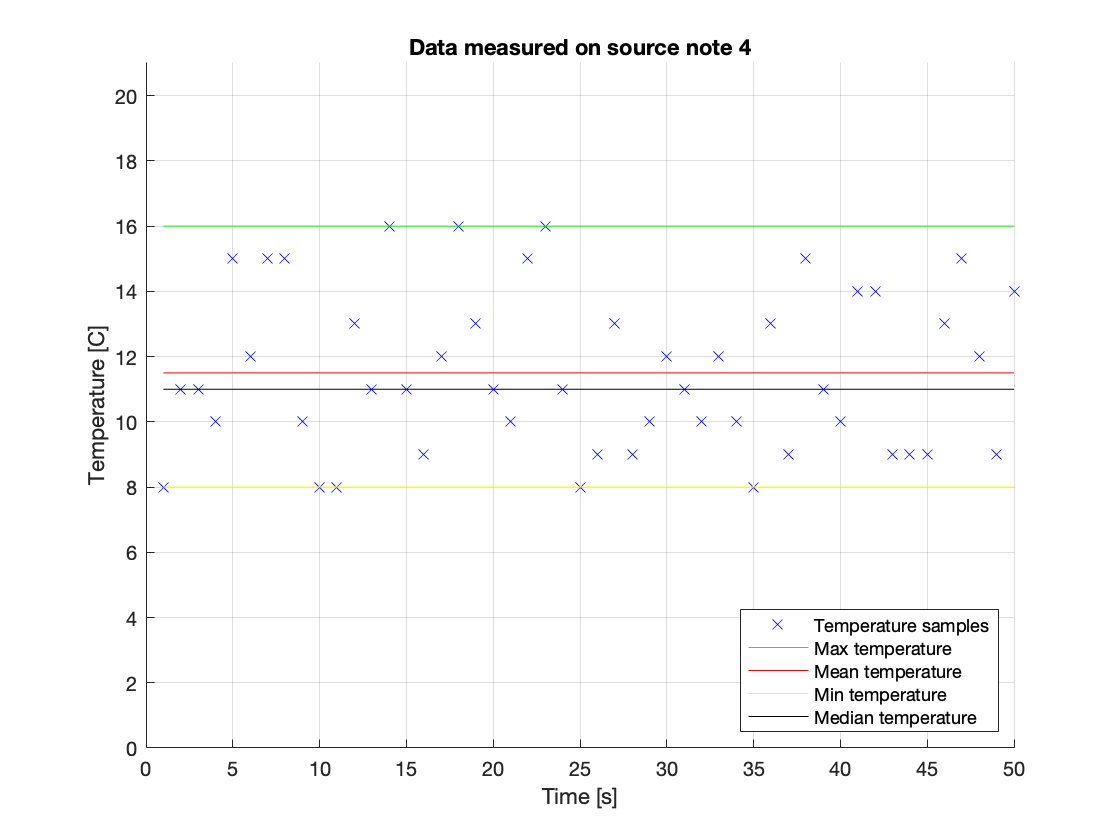

close all
s4_data = source4_data(1:50);
%s4_data = source4_data;
% Calculate mean, min, max and median of sensored data
source4_mean = mean(s4_data);
source4_min = min(s4_data);
source4_max = max(s4_data);
source4_median = median(s4_data);
source4_samples = length(s4_data);

% Plot the sampled and aggregated data
figure(4)
scatter(time, s4_data, 'x', 'b')
ylim([0;max(s4_data)+5]), grid
title('Data measured on source note 4')
xlabel('Time [s]'), ylabel('Temperature [C]')
hold on
plot(time, source4_max*ones(size(time)), 'g')
plot(time, source4_mean*ones(size(time)), 'r')
plot(time, source4_min*ones(size(time)),'y')
plot(time, source4_median*ones(size(time)),'k')
legend('Temperature samples', 'Max temperature', 'Mean temperature', 'Min temperature', 'Median temperature', location='southeast')

## Calculation of global values for scenario 1 & 3

global_data = cat(1,s1_data',s2_data', s3_data', s4_data')';

global_min = min(global_data)

global_min = 8

global_max = max(global_data)

global_max = 30

global_median = median(global_data)

global_median = 18

global_mean = mean(global_data)

global_mean = 17.8300

## Congestion scenario global values - scenario 2

congest_data = cat(1, s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data', s1_data');
total_congest_data = cat(1, congest_data ,s2_data', s3_data', s4_data')';

congest_min = min(total_congest_data)

congest_min = 8

congest_max = max(total_congest_data)

congest_max = 30

congest_mean = mean(total_congest_data)

congest_mean = 20.8537

congest_median = median(total_congest_data)

congest_median = 20

sim1_agg1_power_used = 4737

sim1_agg2_power_used = 5328

sim1_sink_CPU_clocks = 140042

sim1_sink_RX_clocks = 29551121

sim1_sink_power_used = 5328

sim2_sink_RX_clocks = 2953744

sim2_sink_power_used = 5334

sim3_sink_RX_clocks = 2953744

sim3_sink_power_used = 5334

current = 1.7786e+03

ans = 5.3359e+03